problem 1-a

syms x;
Xi=[0,2,4,5];
Fi=[3,4,7,59];
n = 4;
L = lagrangian_interp(n,Xi);
v = 0;
for i=1:n
    v = v+ Fi(i)*L(i);
end
P(x)=vpa(v);
disp('The polynomial is:')

The polynomial is:


disp(simplify(P(x)))

$$3.3166666666666666666666666666667\,x^{3}-19.65\,x^{2}+26.533333333333333333333333333333\,x+3.0$$

disp('The value of F(1) is:')

The value of F(1) is:


disp(subs(simplify(P(1))))

$$13.2$$

problem 1-b

Xi_2 = [Xi, 8];
Fi_2 = [Fi, 84];
m = n + 1;
L = lagrangian_interp(m,Xi_2);
v = 0;
for i=1:m
    v = v+ Fi_2(i)*L(i);
end
P(x)=vpa(v);
disp('The polynomial is:')

The polynomial is:


disp(simplify(P(x)))

$$-0.99270833333333333333333333333333\,x^{4}+14.236458333333333333333333333333\,x^{3}-57.372916666666666666666666666667\,x^{2}+66.241666666666666666666666666667\,x+3.0$$

disp('The value of F(1) is:')

The value of F(1) is:


disp(subs(simplify(P(1))))

$$25.1125$$

problem 2

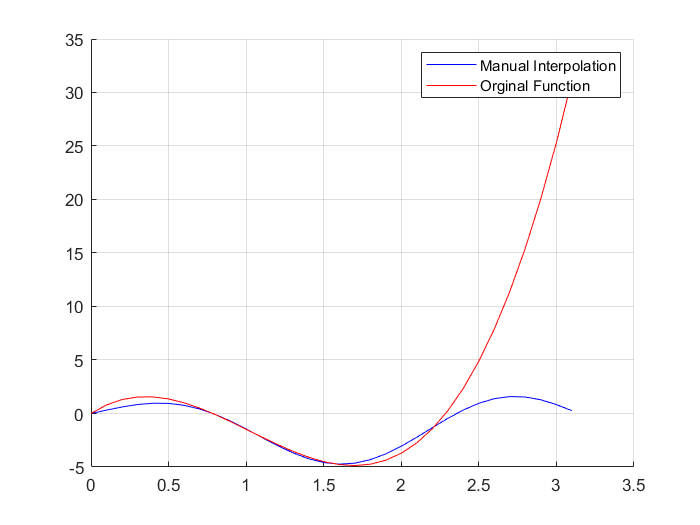

syms x;
m = 4;
f = (pi + x)*cos(2*x)*sin(x);
X=[0,pi/4,pi/3,pi/2];

Farr = eval(subs(f,x,X(1:m)));

L = lagrangian_interp(m,X);
v = 0;
for i=1:m
    v = v+ Farr(i)*L(i);
end
P(x)=vpa(v);
hold on
grid on
xx = 0:0.1:pi;
ff = eval(subs(f,x,xx));
pp = eval(subs(P,x,xx));
plot(xx,ff,'b')
plot(xx,pp,'r')
hold off
legend('Manual Interpolation','Orginal Function')

disp('The polynomial is:')

The polynomial is:


disp(simplify(P(x)))

$$5.3404023102629661264584986006584\,x^{3}-16.402745133057558599053159317946\,x^{2}+9.588457268119893615434292983273\,x$$

problem 3

syms x a b y;
P=(y-a*x-b)^2;
%Here we create the needed arrays and values.
xi = [0 5 10 12 15 20 35 42];
yi=[10 50 120 194 250 281 302 368];
num = 8;
disp('Differentiating:')

Differentiating:


disp(diff(P,a))

$$2\,x\,\left(b-y+a\,x\right)$$

disp(diff(P,b))

$$2\,b-2\,y+2\,a\,x$$

%Hence we can build our system of equations
Equation1=sum(xi.^2)*a+sum(xi)*b==sum(xi.*yi);
Equation2=sum(xi)*a+num*b==sum(yi);
disp('The System of equations:')

The System of equations:


disp(Equation1)

$$3883\,a+139\,b=39174$$

disp(Equation2)

$$139\,a+8\,b=1575$$

%Now we shall solve the equations.
Ans = solve([Equation1, Equation2], [a, b]);
a_Ans = Ans.a;
b_Ans = Ans.b;
% Now we shall display the polynomial
Ans_Pol=vpa(a_Ans*x+b_Ans);
disp(simplify(Ans_Pol))

$$8.0445371710806437877884697266457\,x+57.101166652473814187175338499532$$

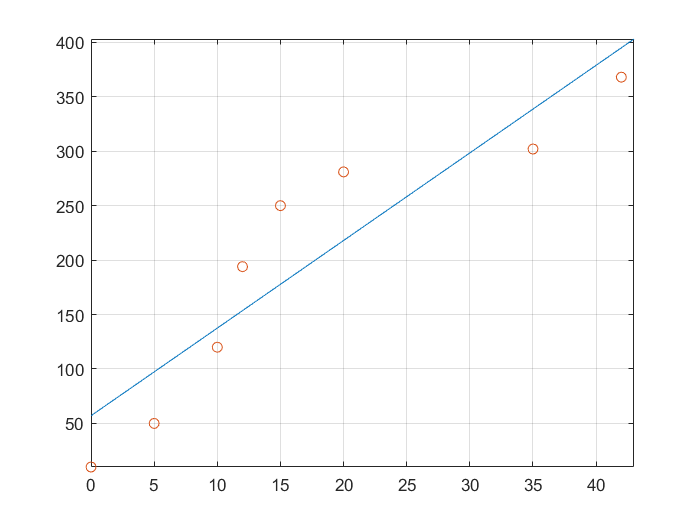

fplot(Ans_Pol,[0 43])
hold on
scatter(xi,yi)
grid on
hold off

problem 4-a

syms x 
e = 0.3;
b = 1;
a = 0;
f = 1/(x^2 + 1);
M2 = abs(eval(subs(diff(f,x,2),x,0)));
h = sqrt(e * 12 * 1/(M2*(b-a)))

h = 1.3416

problem 4-b

syms x
e = 0.0001;
b = 1;
a = 0;
f = 1/(x^2 + 1);
M4 = abs(eval(subs(diff(f,x,4),x,0)));
h = (e * 180 * 1/(M4*(b-a)))^0.25;
n = ceil(1/h);
if rem(n,2) == 1
    n = n + 1;
end
h = 1/n;
I= eval(h/3*(subs(f,x,0)+4*sum(subs(f,x,h:2*h:1-h))+ ...
    2*sum(subs(f,x,2*h:2*h:1-h))+subs(f,x,1)))

I = 0.7854

problem 4-c

x = @(t) (t+1)./2;
f = @(x) 1./(x.^2 + 1);
d = sqrt(3) / 3;
G_I = 0.5 * (f(x(-d)) + f(x(d)))

G_I = 0.7869

function output = lagrangian_interp(n,x_array)
syms x;
j=1;
i=1;
L = sym('x',[1 4]);
for k=1:n
    L(k)=1;
end
while j<=n
    while i<=n
        if(i~=j)
            L(j)=L(j).*(x-x_array(i))/(x_array(j)-x_array(i));
        end
        i=i+1;
    end
    j=j+1;
    i=i-n;
end
output = L;
end